## The Manny Ramirez problem

Manny Ramirez is a former member of the Boston Red Sox (an American baseball team) who was notorious for his relaxed attitude and taste for practical jokes. The objective of this case study objective in this chapter is to solve the following Manny-inspired problem:

*What is the minimum effort required to hit a home run in Fenway Park?*

Fenway Park is a baseball stadium in Boston, Massachusetts. One of its most famous features is the “[Green Monster](https://en.wikipedia.org/wiki/Green_Monster)", which is a wall in left field that is unusually close to home plate, only 310 feet away. To compensate for the short distance, the wall is unusually high, at 37 feet.

We want to find the minimum velocity at which a ball can leave home plate and still go over the Green Monster. We’ll proceed in the following steps:

- We'll model the flight of a baseball, taking into account air resistance and gravity, and implement the model using ode45.

- For a given initial velocity, we’ll find the optimal "launch angle", that is, the angle the ball should leave home plate to maximize its height when it reaches the wall.

- Then we’ll find the minimal velocity that clears the wall, given that it has the optimal launch angle.

### Modeling baseball

To model the flight of a baseball, we have to make some modeling decisions. To get started, we ignore any spin that might be on the ball, and the resulting [Magnus force](http:// https://en.wikipedia.org/wiki/Magnus_effect). Under this assumption, the ball travels in a vertical plane, so we’ll run simulations in two dimensions, rather than three.

Air resistance has a substantial effect on most projectiles in air, so we will include a drag force.

To model air resistance, we’ll need the mass, frontal area, and drag coefficient of a baseball. [Mass and diameter are easy to find](https://en.wikipedia.org/wiki/Baseball_(ball)). Drag coefficient is only a little harder; according to [*The Physics of Baseball*](https://www.amazon.com/Physics-Baseball-3rd-Robert-Adair/dp/0060084367), the drag coefficient of a baseball is approximately 0.33 (with no units).

In reality, this value *does* depend on velocity. At low velocities it might be as high as 0.5, and at high velocities as low as 0.28.

Furthermore, the transition between these regimes typically happens exactly in the range of velocities we are interested in, between 20 and 40 meters per second.

Nevertheless, we’ll start with a simple model where the drag coefficient does not depend on velocity.

Let's simulate the flight of a baseball that is batted from home plate at an angle of 45 degrees and initial speed 40 meters per second.

Using the center of home plate as the origin, the x-axis is parallel to the ground; the y-axis is vertical.  The initial height is about 1 meter.

Here are the parameters we need:

clear all

% initial x and y coordinates
params.x = 0; % m 
params.y = 1; % m

% acceleration due to gravity
params.g = 9.8; % m/s**2

% mass and diameter of a baseball from 
% https://en.wikipedia.org/wiki/Baseball_(ball)
params.mass = 145e-3; % kg
params.diameter = 73e-3; % m

% density of air at 20 C near sea level
params.rho = 1.2; % kg/m**3

% coefficient of drag for a baseball
params.C_d = 0.33;  % dimensionless

% launch angle and initial speed
params.launch_angle = 45; % degree
params.speed = 40; % m / s

params

params = struct with fields:
               x: 0
               y: 1
               g: 9.8000
            mass: 0.1450
        diameter: 0.0730
             rho: 1.2000
             C_d: 0.3300
    launch_angle: 45
           speed: 40


`run_ode_solver` takes params as an input variable, runs `ode45`, and returns the results.

[T, M] = run_ode_solver(params);

The x and y coordinates are the first two columns of `M`.

X = M(:, 1);
Y = M(:, 2);

We can  extract the final position and time like this.

t_final = T(end)

t_final = 5.0049

x_range = X(end)

x_range = 99.3110

To visualize the results, we can plot `X` and `Y` as a function of time.

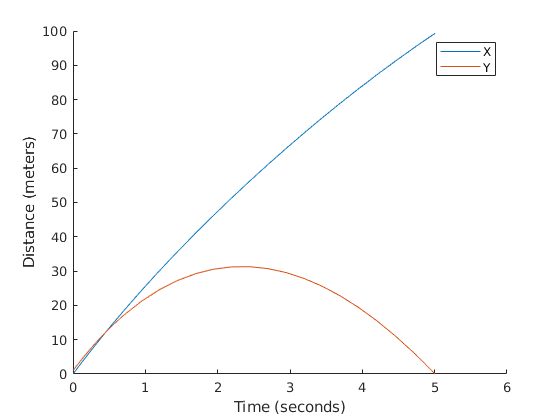

hold on
plot(T, X)
plot(T, Y)
xlabel('Time (seconds)')
ylabel('Distance (meters)')
legend('X', 'Y')

Or, by plotting `Y` versus `X`, we can see the trajectory of the ball.

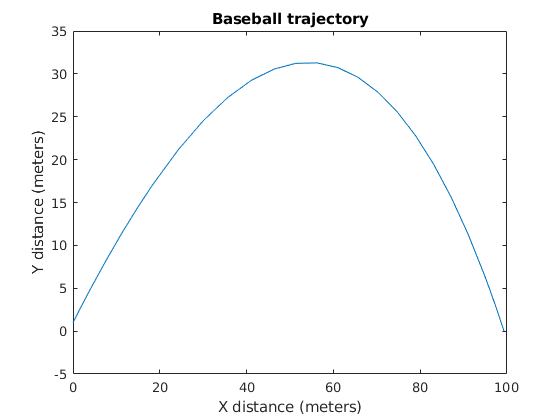

figure()
plot(X, Y)
xlabel('X distance (meters)')
ylabel('Y distance (meters)')
title('Baseball trajectory')

### Optimal launch angle

As the next step toward solving the Manny Ramirez problem, we have to find the optimal launch angle for the given initial speed.

The following loop tries a range of angles and plots `x_range`, which is the distance the ball flies in the air.

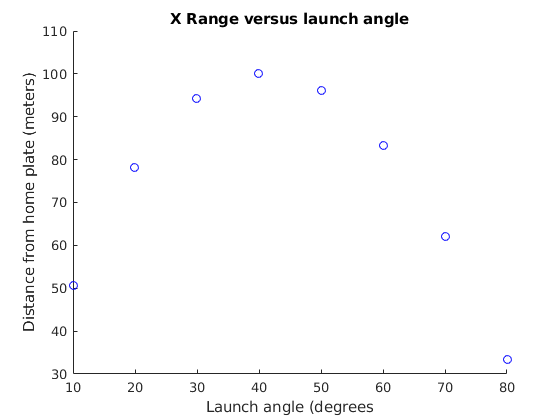

figure()
hold on
for launch_angle=linspace(10, 80, 8)
    params.launch_angle = launch_angle;
    [T, M] = run_ode_solver(params);
    X = M(:, 1);
    x_range = X(end);
    plot(launch_angle, x_range, 'bo')
end
xlabel('Launch angle (degrees')
ylabel('Distance from home plate (meters)')
title('X Range versus launch angle')

This figure is visually similar to the trajectory of the baseball, but don't get them confused.  This figure shows how far the ball travels as a function of launch angle.

It looks like the maximum is near 40 degrees.  To estimate it more precisely, we can use `fminsearch`.  It took the code from the previous loop and put it into a function called `range_func`, which takes launch angle as an input variable and returns x range.

[x, fval] = fminsearch(@(x) -range_func(x, params), 40)

x = 40.8749

fval = -100.1183

With the initial velocity 40 m/s, the launch angle that maximizes range is about 41 degrees.

In the next notebook, we'll take it from here and finish off the Manny Ramirez problem.

### Functions

function [T, M] = run_ode_solver(params)
    % Simulate the flight of a baseball.
    
    % Compute the initial condition vector
    theta = deg2rad(params.launch_angle);
    [vx, vy] = pol2cart(theta, params.speed);
    init = [params.x, params.y, vx, vy];
    
    % compute baseball area (for drag force)
    radius = params.diameter/2;
    area = pi * radius^2;
    
    % Test the slope function
    slope_func(0, init);
    
    options = odeset('Events', @event_func);
    
    % Run ode45
    tspan = [0, 10];  % seconds
    [T, M] = ode45(@slope_func, tspan, init, options);
    
    function res = slope_func(t, X)
        % Compute slope for the baseball model.
        [x, y, vx, vy] = matsplit(X);
        
        V = [vx, vy];
        a_drag = drag_force(V) / params.mass;
        a_grav = [0, -params.g];
    
        A = a_grav + a_drag;
        
        res = [vx; vy; A(1); A(2)];
    end
    
    function [value, isterminal, direction] = event_func(t, X)
        % Stop when the ball hits the ground.
        [x, y, vx, vy] = matsplit(X);
        value = y;
        isterminal = 1;
        direction = -1;
    end
    
    function res = drag_force(V)
        % Compute the drag force on a baseball.
        rho = params.rho;
        C_d = params.C_d;
        mag = -rho * norm(V)^2 * C_d * area / 2;
        direction = hat(V);
        res = direction * mag;
    end
end

function res = hat(V)
    % Compute a unit vector in the direction of V.
    res = V / norm(V);
end
    
function res = range_func(launch_angle, params)
    % Simulate a baseball with the given launch angle
    % and return the distance traveled.
    params.launch_angle = launch_angle;
    [T, M] = run_ode_solver(params);
    X = M(:, 1);
    res = X(end);
end

function varargout = matsplit(A,dim)
%MATSPLIT Split matrix elements into separate variables.
%   VARARGOUT = MATSPLIT(A) returns each element of the array A in a
%   separate variable defined by VARARGOUT.
%
%   VARARGOUT = MATSPLIT(A,DIM) only splits the matrix in one dimension. If
%   DIM=1, each column vector is assigned to an output variable. If
%   DIM=2, each row vector is assigned to an output variable.
%
%   MRE 11/12/14 (last updated 11/13/14)
%   https://www.mathworks.com/matlabcentral/fileexchange/48439-matsplit
    if nargin==1
        varargout = num2cell(A);
    else
        varargout = num2cell(A,dim);
    end
end